# **Matlab案例代码解析**

## 4. 图像信号处理案例

### 4.2 图像分割

#### 4.2.3 区域生长

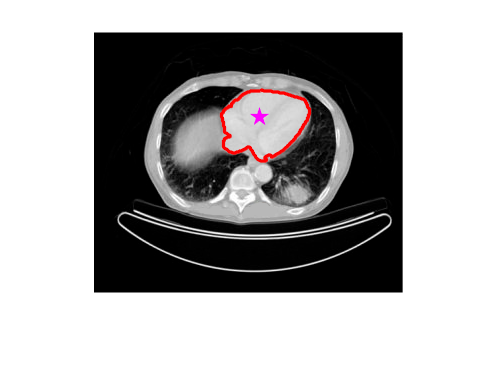

clear;clc;
img = imread('test.bmp');
imshow(img);
% RGB 图转灰度图
if length(size(img)) > 2
    I = rgb2gray(img); 
else
    I = img;
end
% 转成浮点数格式
I = double(I);
% 设置种子点
% p1 = ginput(1);
% x = round(p1(2));
% y = round(p1(1));
x = 85;
y = 166;
% 阈值
threshold = 20;
% 获取 ROI
J = RegionGrowing(I, [x, y], threshold);
% 根据 ROI 确定边界
[bound, F] = RegionBoundary(J);
hold on 
plot(y, x, 'pm', 'MarkerSize', 10, 'MarkerFaceColor', 'm')
plot(bound(:, 1), bound(:, 2), 'r', 'LineWidth', 2)
hold off